# Deep Chimpact: Depth Estimation for Wildlife Conservation 

Team K_A

## 1 **Introduction**

We used an action recognition pretrained network (ResNet3D_18) for this competition. To predict the distance at time "t" we provided the network with 15 frames from different timestamps (t-5,t-2,t-1.5,t-1,t-0.75,t-0.5,t-0.25, t, t+0.25, t+0.5, t+0.75, t+1, t+1.5, t+2, t+5) and saved them as mat files. At time "t", we used the estimated bounding box info for masking (as you can see in **Figure1**), in case it is provided by the metadata. We used multiple random augmentations (e.g., Scale, XReflection, Hue, rgb2gray) when loading batches of processed videos (mat files) for training. 

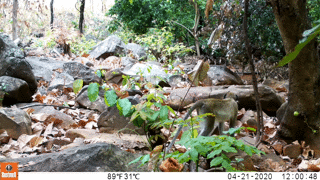

**Figure1.** 15 frames that are used for predicting the distance  

## 2 The Data

We used the original for training and testing. We downloaded the original training and testing videos and placed them in "./Data/Train_videos/" and "./Data/Test_videos/" directories.

### 2.1 Load labels and metadata

This section is based on the benchmark code. In this section, we loaded the Labels and metadata.

location="./Data/Tables/";
labels = readtable(location+"train_labels.csv");
labels.time=labels.time; % Synching time with images
head(labels)

ans = 8×3 table
      video_id      time    distance
    ____________    ____    ________

    {'aany.mp4'}      0         3   
    {'aany.mp4'}     10         4   
    {'aany.mp4'}     20         4   
    {'aazh.avi'}      0       1.5   
    {'aazh.avi'}      2       1.5   
    {'aazh.avi'}      4       1.5   
    {'aazh.avi'}      6       1.5   
    {'aazh.avi'}      8       1.5   


metadata = readtable(location+"train_metadata.csv");
head(metadata)

ans = 8×9 table
      video_id      time       x1          y1         x2         y2       probability          park          site_id
    ____________    ____    _________    _______    _______    _______    ___________    ________________    _______

    {'aany.mp4'}      0             0    0.41909    0.32064    0.88888       0.7334      {'moyen_bafing'}    {'fat'}
    {'aany.mp4'}     10       0.59689    0.49076     0.9092    0.77066      0.21809      {'moyen_bafing'}    {'fat'}
    {'aany.mp4'}     20       0.68722    0.56837    0.98108    0.85366      0.21932      {'moyen_bafing'}    {'fat'}
    {'aazh.avi'}      0     0.0096875    0.36197    0.46504    0.92391      0.73643      {'t

## 3 Process Video Files

We modified the benchmark code to cut the video of interest for time "t" from the original video. The **readvideo** function in the helper functions section, reads videos and extracts frames at timestamps of t-5,t-2,t-1.5,t-1,t-0.75,t-0.5,t-0.25, t, t+0.25, t+0.5, t+0.75, t+1, t+1.5, t+2, t+5 to predict distance at time "t". 

Finally, it saves these 15 extracted frames as a single mat file. 

### 3.1 Train videos preprocessing

Train_data="./Data/Train_videos/" ; % Location of training videos
destination_folder="./Data/TrainData/"; % Destination of Processed data
train_metadata = readtable(location+"train_metadata.csv"); % Metadata for training data   
imds = imageDatastore(Train_data,...
                      'ReadFcn',@(filename)readvideo(filename,train_metadata,...
                      destination_folder),...
                      'FileExtensions',{'.mp4','.avi'});

### 3.2 Test videos preprocessing

Test_data="./Data/Test_videos/" ; % Location of testing videos
destination_folder_test="./Data/TestData/"; % Destination of Processed data
test_metadata = readtable(location+"test_metadata.csv"); % Metadata for test data   
imds_test = imageDatastore(Test_data,...
                      'ReadFcn',@(filename)readvideo(filename,test_metadata,...
                      destination_folder_test),...
                      'FileExtensions',{'.mp4','.avi'});

### 3.3 Preprocessing videos 

% Preprocessing all train data;
if ~exist("./Data/TrainData","dir")
    mkdir TrainData
    imds.readall("UseParallel", true);
end

% Preprocessing all test data
if ~exist("./Data/TestData","dir")
    mkdir TestData
    imds_test.readall("UseParallel", true);
end


## 4 Load Pretrained Network

In this section, we load the pretrained 3D network that is trained for action recognition. You can find details about converting the pretrained network from PyTorch to MATLAB in files "Convert_onnxruntime.py" and "convert_onnx_to_lgraph.mlx" in "Imp_R3D" directory.

load("./Imp_R3D/lgarph_R3D.mat");

### 4.1 Analyze network

This function checks the imported network.

analyzeNetwork(lgraph)

## 5 Prepare Training Data

In this section, we used two random data partitions (seeds: rng(7) & rng(13)) to split the data to training and validation videos. Each time, we used 80 percent of unique videos for training and 20 percent for validation (By unique videos, we mean that a video was selected with its entire timestamps rather than choosing some timestamps from it). We used this approach (randomly splitting the data to 80/20 training/validation) in the interest of time. However, a better practice would be to use k-folds cross-validation.

Splitting the training data to train and validation: 

% rng(7 & 13) are used for developing the highest private score with MATLAB
rng(7) % For the second random fold you can change the random number generator to rng(13) 
old = "./Data/TrainData/";
new = "./Data/TrainData/Validation/";
if ~exist(new,"dir")
    mkdir "./Data/TrainData/Validation/"
else
    try
        movefile("./Data/TrainData/Validation/*.mat", old);
    catch
        
    end
end
% Finding number of unique videos in training metadata
vid_name=unique(metadata(:,1));
n_vid= numel(vid_name);
n_training_id = randperm(n_vid);
% Separate data to training and validation
vid_name_tr = vid_name(n_training_id(1:round(0.8*n_vid)),1);
idx=1:size(metadata(:,1),1);
trainingIdx=idx(ismember(metadata{:,1},vid_name_tr{:,1}));
validationIdx=idx(~ismember(metadata{:,1},vid_name_tr{:,1}));
n_training=numel(trainingIdx);
validation_metadata=metadata(validationIdx,:);
valid_files = strcat(erase(erase(validation_metadata.video_id,'.mp4'),'.avi'),...
    string(validation_metadata.time),".mat");

% Moving validation data to "./Data/TrainData/Validation/" directroey
for k = 1:numel(valid_files)
    movefile(fullfile(old,valid_files{k}),new);
end

Creating training and validation datastores:

imageDS_train = imageDatastore("./Data/Traindata/",...
    "FileExtensions",".mat", "ReadFcn",@(x) matRead(x,true));
imageDS_valid = imageDatastore("./Data/Traindata/Validation/",...
    "FileExtensions",".mat", "ReadFcn",@(x) matRead(x,false));

Adding labels to the created datastores:

%Train
labelDS_train = generateLabelDS(imageDS_train,labels);
trainingDS = combine(imageDS_train, labelDS_train);
%Validation
labelDS_valid= generateLabelDS(imageDS_valid,labels);
validationDS = combine(imageDS_valid, labelDS_valid);


## 6 Specify Training Options

Specifying training options:

miniBatchSize=4;
validationFrequency = floor(n_training/(miniBatchSize));

options = trainingOptions('adam', ...
    'LearnRateSchedule','piecewise', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',20, ...
    'InitialLearnRate',0.0001, ...
    'LearnRateDropFactor',0.3,...
    'LearnRateDropPeriod',10,...
    'Shuffle','every-epoch', ...
    'ValidationData',validationDS, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'Verbose',true, ...
    'VerboseFrequency',1000,...
    'OutputNetwork', 'best-validation-loss',...
    'ExecutionEnvironment',"multi-gpu");

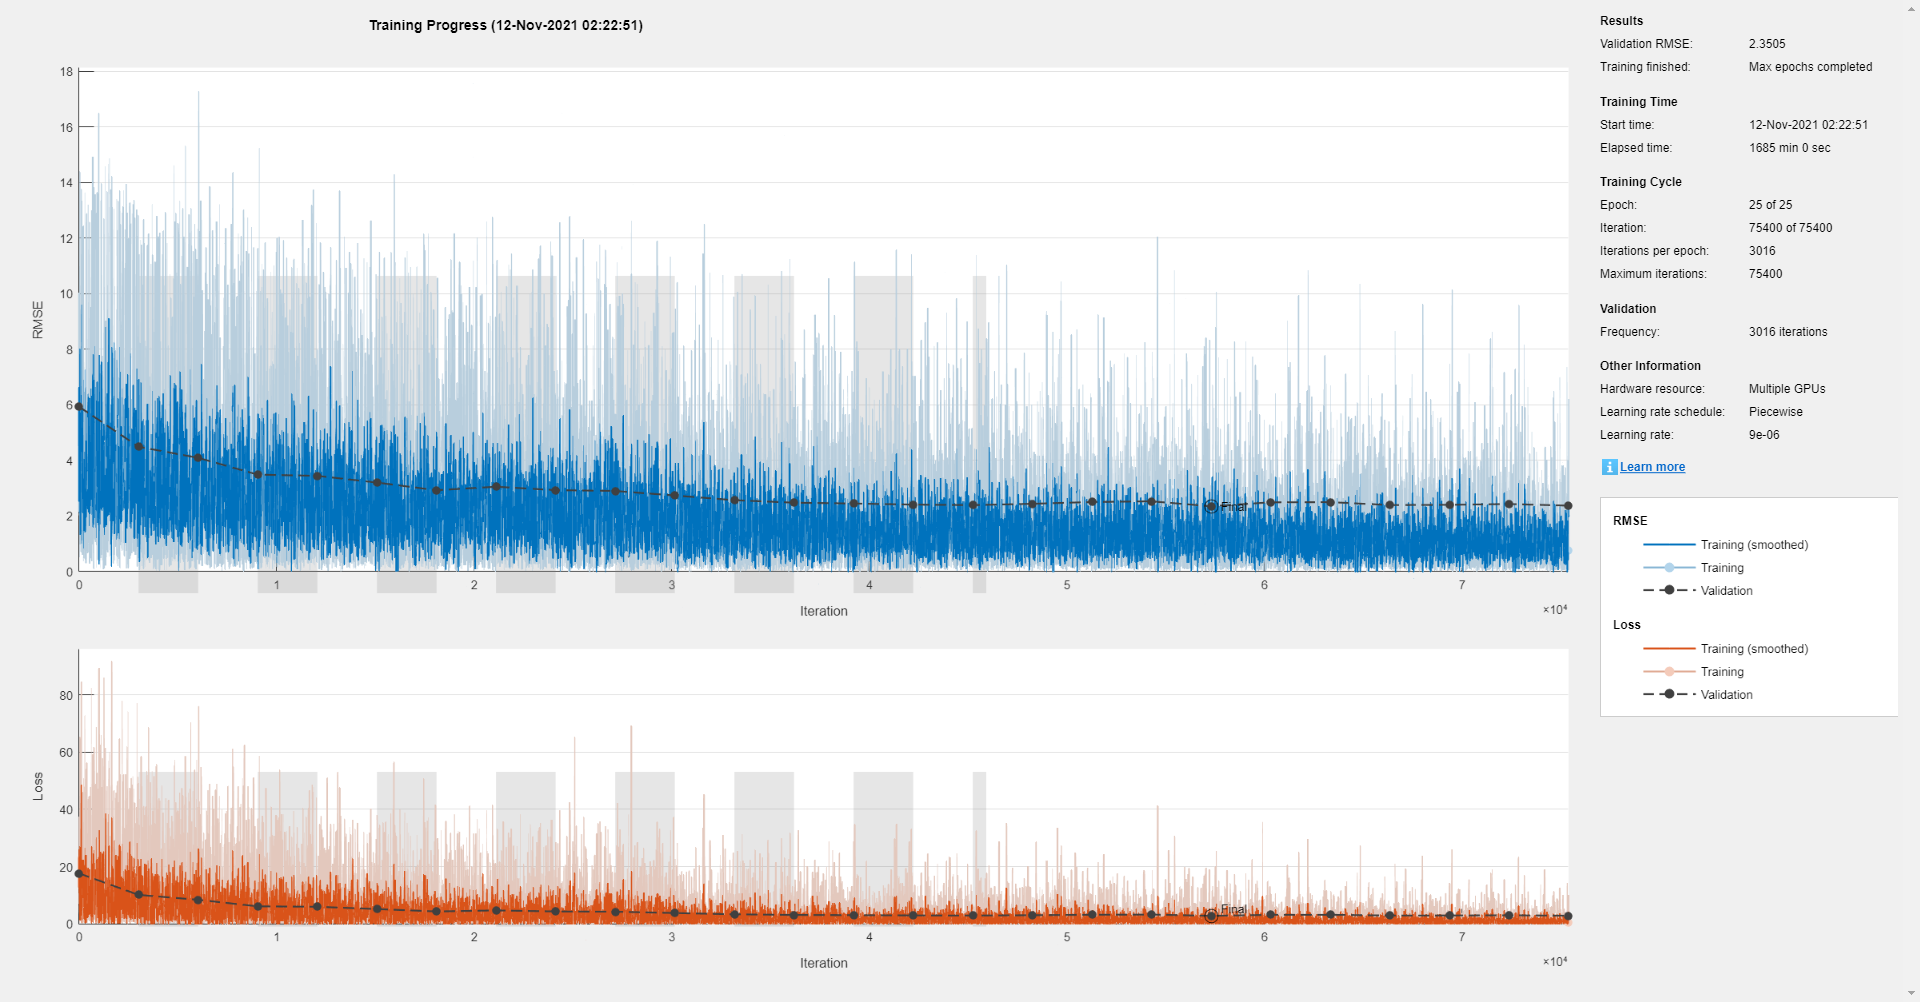

## 7 Train the Network

In this section, we train the network. However, in the code below train_network is set to false because the networks were already trained and are just loaded in here. If you wish to train the network from the beginning, you can change the option to true. A GPU with at least 16 GB memory is needed for training the algorithm.

train_network=false; % If you wish to train the network change this value to true
if train_network==true
    [net,info] = trainNetwork(trainingDS,lgraph,options);
    save('trainedNetwork.mat','net')
else
    % Load pretrained network (R7 & R13). If you want to use R13, change
    % random number generator to rng(13) in "Section 5 Prepare Training Data"
    net_name="R7";
    net=load("./Data/Pretrained_networks/trainedNetwork_"+net_name+".mat").net;
end


## 8 Validation Accuracy:

obtaining accuracy of model for validation data:

imageDS_valid.reset
for ii=1:size(validationDS.UnderlyingDatastores{1,1}.Files,1)
    distance_val(ii) = double(predict(net,imageDS_valid.read,'ExecutionEnvironment','gpu')); % Predictions
end
validationDS.reset
for ii=1:size(validationDS.UnderlyingDatastores{1,1}.Files,1)
    distance_val_label(ii) = validationDS.read{2} ; % Labels
end

  rmse= (immse(distance_val,distance_val_label))^0.5

rmse = 2.4594

  mae=mean(abs(distance_val-distance_val_label))

mae = 1.5395

## 9 Prediction 

### 9.1 Predicting distance for training data

In this section, we predict the distance for all data (i.e., training and validation but not testing) using the trained networks. We use the results of this section in the postprocessing step. 

% Predicting all data
location="./Data/Tables/";
submission = readtable(location+"train_labels.csv");
all_address="./Data/TrainData/";
for ii=1:size(submission)
    [~, name] = fileparts(submission.video_id{ii});
    fullname= all_address+name+string(submission.time(ii))+".mat";
    try
        inp = load(fullname);
    catch
        fullname= all_address+"validation/"+name+string(submission.time(ii))+".mat";
        inp = load(fullname);
     end
    f = fields(inp);
    source=inp.(f{1});
    source=permute(source,[3,1,2,4]);
    distance_all(ii,1) = double(predict(net,source,...
        'ExecutionEnvironment','gpu'));
end

% Replacing negative values with zero
distance_all(distance_all<0) = 0;
% Saving the predictions
location="./Data/Tables/";
train_pred = readtable(location+"train_labels.csv");
train_pred.distance=distance_all;
writetable(train_pred, "./Results/"+"Train_pred_"+net_name+".csv");

### 9.2 Predicting distance for testing data

% Predicting testing data
location="./Data/Tables/";
submission = readtable(location+"submission_format.csv");
test_address="./Data/TestData/";
for ii=1:size(submission)
    [~, name] = fileparts(submission.video_id{ii});
    fullname= test_address+name+string(submission.time(ii))+".mat";
    inp = load(fullname);
    f = fields(inp);
    source=inp.(f{1});
    source=permute(source,[3,1,2,4]);
    distance_test(ii,1) = double(predict(net,source,...
        'ExecutionEnvironment','gpu'));
end

% Replacing negative values with zero
distance_test(distance_test<0) = 0;
% Saving the predictions
location="./Data/Tables/";
submission = readtable(location+"submission_format.csv");
submission.distance=distance_test;
writetable(submission, "./Results/"+"Test_pred_"+net_name+".csv");

## 10 Helper Functions

### 10.1 Video pre-processing 

This helper function extracts and pre-processes 15 frames for each row of training metadata. Then it resizes them and saves them as single videos (in mat format). We mask the frame at the time of interest ("t") whenever bounding box information is available.

function output = readvideo(filename, metadata, folder)
    % Load video
    vr = VideoReader(filename);
    H =vr.Height;
    W = vr.Width;

    [~, name] = fileparts(filename);
    idx = contains(metadata.video_id,name);
    videoMetadata = metadata(idx,:);
    
    n_Frames = height(videoMetadata);
    vid_len=vr.Duration;

    
    for i = 1:n_Frames
        % Preallocating the output video arrays
        output = uint8(zeros(180,320,15,3));
        t = videoMetadata.time(i); % Extracting timestamp
        file = fullfile(folder, [name num2str(t) '.mat']); % Generating file name
        time_point=[-5,-2,-1.5,-1,-.75,-.5,-.25,0,.25,.5,.75,1,1.5,2,5];
        if ~isfile(file)
            vr.CurrentTime = t;
            for jj=-7:7
                try
                    vr.CurrentTime = (t+time_point(jj+8));
                    f = readFrame(vr);
                catch
                    if (t+time_point(jj+8)) <= 0
                        vr.CurrentTime = 0.1;
                        f = readFrame(vr);
                    elseif (t+time_point(jj+8)) >= vid_len
                        vr.CurrentTime = (vid_len-0.1);
                        f = readFrame(vr);
                    else
                        disp([name, string(t)])
                    end

                end

                if ~isnan(videoMetadata.x1(i))
                     
                    if jj==0
                        % Extracting corners of bounding box
                        x1 = videoMetadata.x1(i);
                        x2 = videoMetadata.x2(i);
                        y1 = videoMetadata.y1(i);
                        y2 = videoMetadata.y2(i);
        
                        % Masking using bounding box
                        mask = poly2mask([x1 x2 x2 x1]*W,[y1 y1 y2 y2]*H,H,W);
                        maskedFlow = bsxfun(@times, f,...
                            cast(mask, 'like', f));
                        f=maskedFlow;
                    end

                    f = imresize(f,'OutputSize',[180 320]);
                else

                    f = imresize(f,'OutputSize',[180 320]);
                end

                output(:,:,(jj+8),:) = uint8(f);
            end


            if isfolder(folder)
                save(file,'output')
            else
                mkdir(folder)
                save(file,'output')
            end
        end
    end
end

### 10.2 Loading processesd mat files

This helper function loads the mat files (processed videos) from the hard drive and applies different series of random augmentation on each input video to be used for training the network.

function data = matRead(filename,augment_img)
inp = load(filename);
f = fields(inp);
source=inp.(f{1});
if augment_img

    rng("shuffle")
    random_Seed=randi([1, 10^7],1);
    rand0=rand;

    if rand0>=0.5

        rand1=rand;
        rand2=rand;

        for ii=1:size(source,3)
            rng(random_Seed)
            img=squeeze(source(:,:,ii,:));

            tform = randomAffine2d('XTranslation',[-25 25],'YTranslation',[-25 25]);
            outputView = affineOutputView(size(img),tform);
            img = imwarp(img,tform,'OutputView',outputView);
            tform = randomAffine2d('Scale',[1.0,1.3]);
            outputView = affineOutputView(size(img),tform);
            img = imwarp(img,tform,'OutputView',outputView);
            tform = randomAffine2d('XReflection',true,'YReflection',false);
            outputView = affineOutputView(size(img),tform);
            img = imwarp(img,tform,'OutputView',outputView);



            if rand1 >= 0.75
                img = jitterColorHSV(img,'Hue',[0.0 0.15]);
                img = jitterColorHSV(img,'Saturation',[-0.4 0.1]);
                img = jitterColorHSV(img,'Brightness',[-0.3 0.1]);
                img = jitterColorHSV(img,'Contrast',[1 1.4]);
            end


            if rand2 >= 0.7
                img=repmat(rgb2gray(img),[1 1 3]);
            end

            source(:,:,ii,:)=img;

        end
    end
end
%% changing the axis
source=permute(source,[3,1,2,4]);
data = source;
end

### 10.3 Create arrayDatastore for responses

This function is adapted from the benchmark code.

function labelDS = generateLabelDS(imds,labels)
    files = imds.Files;
    n_files = length(files);
    dataLabels = zeros(n_files,1);
    for i = 1:n_files
        [~,id] = fileparts(files{i});
        video = id(1:4);
        time = str2double(id(5:end));
        idx = (contains(labels.video_id,video)) & (labels.time == time);
        dataLabels(i) = labels.distance(idx);
        
    end
    labelDS = arrayDatastore(dataLabels);
end
